# Verificação nFNC

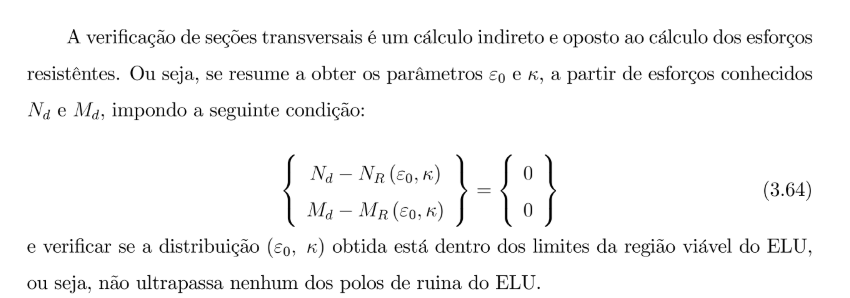

#### Assim, uma alternativa para a resolução desse problema é a utilização do método de Newton-Raphson

Definindo o material:

clear;
gamaf = 1.4;
gamac = 1.4;
gamas = 1.15;
Es = 210*10^3;

tipoc = 60; %definicoes de material %esta em MPa
tipos = 50; %nao esta em MPa

### Geometria da seção

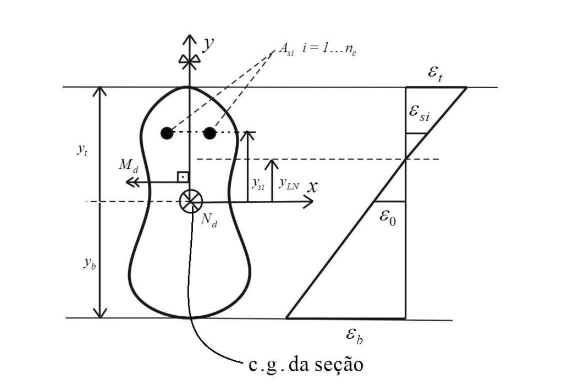


b = 0.25; %variaveis de geometria retangular
h = 0.70;
A = b*h;
S = 0;

ytopo = +h/2;
ybase = -h/2;
diametro = 20*10^(-3);
nc = 3;
ys = [-0.30 -0.22 0.30]; %coordenadas da armadura a partir do centro geométrico
nbarras = [2 2 2];
As = 0.25*diametro^2*pi*nbarras;
[etac,sigmacd,epsilonc2,epsiloncu,n] = paramsConcreto(tipoc,gamac);
[fyd,epsilonyd] = paramsaco(tipos,Es,gamas);


### Esforços a serem verificados:

Nd = 6.902;
Md = 0.0;

### Como funciona o algoritmo:

#### Para uma função no espaço xy, o algoritmo de Newton-Raphson é esse:

#### No entanto estamos trabalhando com:

#### 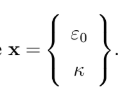  

#### Expandindo:

#### 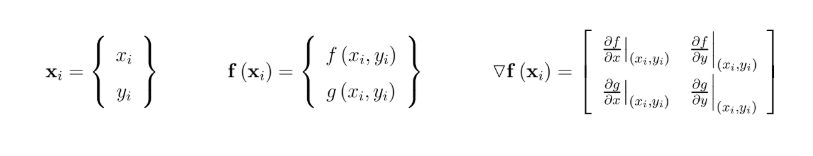

#### 

#### Ou seja,

#### 

#### Fazendo as devidas substituições:

#### 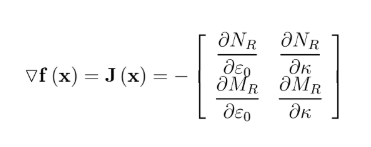

### Então o algoritmo se resume a 

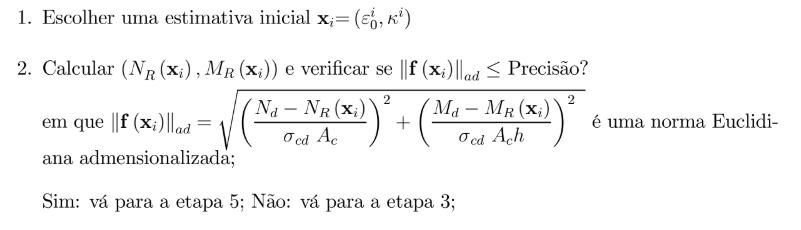

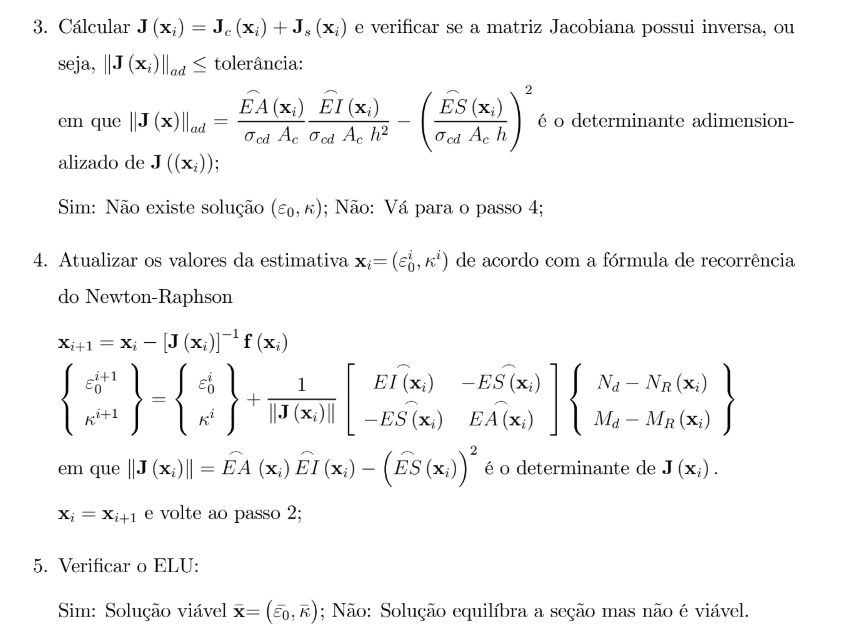

precisao = 1e-10;
tolerancia = 1e-10;
maxit = 1000;

epsilon0 = 0.0; %chute inicial de epsilon0
k = 0.0; %chute inicial da curvatura

Obs: O chute inicial da curvatura e do epsilon0 sempre deve ser 0, pois a matriz nunca será singular, mas isso será aprofundado pelas apostilas

f = 1; %norma de f para entrar no loop
Det = 1; %determinante da Jacobiana

DADOS = [0 0 0 0 0 0 0 0 0 0 0 0];

cont = 1;

Antes de entrar no loop, definiremos Js e Jc:

### Contribuição do Aço

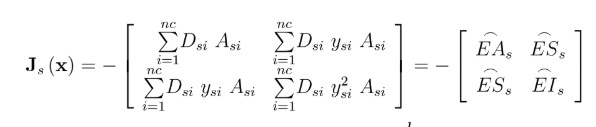

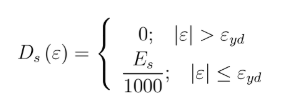

while (cont <= maxit && f >= precisao*(Nd^2+Md^2)^0.5 && abs(Det) >= tolerancia*(sigmacd^2)*b^2*h^4/12 )
    %Cálculo para a armadura;
    Ns = 0;
    Ms = 0;
    EAs = 0;
    ESs = 0;
    EIs = 0;

    for i=1:nc
        epsilonsi = epsilon0 +k*ys(i);
        Ns = Ns + sigmasi (epsilonsi, fyd, epsilonyd)*As(i);
        Ms = Ms + sigmasi(epsilonsi , fyd, epsilonyd)*As(i)*ys(i);
        EAs = EAs + dsigmasi(epsilonsi , epsilonyd, fyd)*As(i);
        ESs = ESs + dsigmasi(epsilonsi , epsilonyd, fyd)*As(i)*ys(i);
        EIs = EIs + dsigmasi(epsilonsi , epsilonyd, fyd)*As(i)*(ys(i)^2);
    end

    %Cálculo para o concreto
    epsilontopo = epsilon0 + k*ytopo;
    epsilonbase = epsilon0 + k*ybase;

Pela definição

## Esforços do aço:

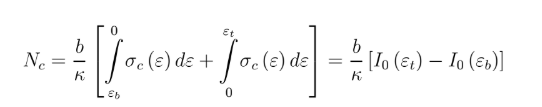

### Contribuição do Concreto

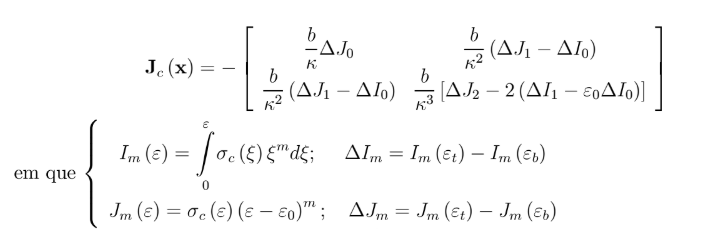

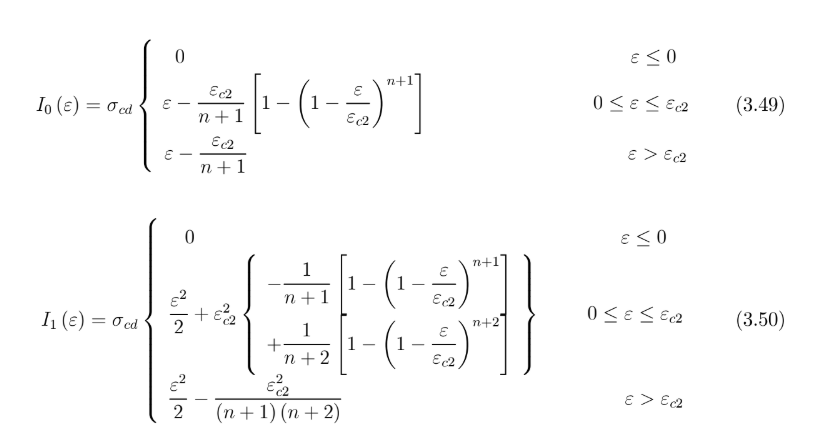

Nesse código, calculamos em termos de** EA,EI,ES,** pois temos como referência essa matriz:

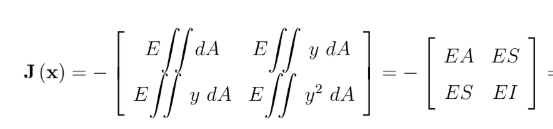

    %Valores de I
    I0et = pot_aux (epsilontopo,sigmacd,epsilonc2,n,0);
    I0eb = pot_aux (epsilonbase,sigmacd,epsilonc2,n,0);
    I1et = pot_aux (epsilontopo,sigmacd,epsilonc2,n,1);
    I1eb = pot_aux (epsilonbase,sigmacd,epsilonc2,n,1);

    %Valores de J
    J0et = sigmac(epsilontopo, epsilonc2, sigmacd, n);
    J0eb = sigmac(epsilonbase, epsilonc2, sigmacd, n);
    J1et = sigmac(epsilontopo, epsilonc2, sigmacd, n)*(epsilontopo - epsilon0);
    J1eb = sigmac(epsilonbase, epsilonc2, sigmacd, n)*(epsilonbase - epsilon0);
    J2et = sigmac(epsilontopo, epsilonc2, sigmacd, n)*((epsilontopo - epsilon0)^2);
    J2eb = sigmac(epsilonbase, epsilonc2, sigmacd, n)*((epsilonbase - epsilon0)^2);

    %Calculando os valores de Nc e Mc
    if abs(k*h) < 10^(-5)
        Nc = sigmac(epsilon0,epsilonc2, sigmacd, n)*A;
        Mc = 0;
        EAc = dsigmac(epsilon0, epsilonc2, n, sigmacd)*b*h;
        ESc = 0;
        EIc = dsigmac(epsilon0, epsilonc2, n, sigmacd)*b*(h^3)/12;
    else 
        Nc = (b/k)*(I0et - I0eb);
        Mc = (b/k^2)*((I1et-I1eb) - epsilon0*(I0et-I0eb));
        EAc = (b/k)*(J0et-J0eb);
        ESc = (b/k^2)*((J1et - J1eb)-(I0et- I0eb));
        EIc = (b/k^3)*((J2et - J2eb) - 2*((I1et - I1eb) - epsilon0*(I0et-I0eb)));
    end

     %Cálculo dos esforços e rigidezes totais
     Nr = Nc + Ns;
     Mr = Mc + Ms;
     EA = EAs + EAc;
     ES = ESs + ESc;
     EI = EIs + EIc;
     Det = EA*EI - ((ES)^2);

     f = sqrt( (Nd- Nr)^2 + (Md - Mr)^2);

     DADOS = [DADOS;[cont epsilon0 k Nr Mr f EA ES EI Det epsilontopo epsilonbase]];

Nessa linha, verificamos se a matriz se tornou singular, caso tenha se tornado, não é possível encontrar uma solução pro sistema

     if (abs(Det) > tolerancia*sigmacd^2*b^2*h^4/12)
         epsilon0 = epsilon0 + (1/Det)*( EI*( Nd-Nr )- ES*( Md- Mr ));
         k = k +(1/Det)*( -ES*( Nd - Nr) +EA*( Md - Mr ));
     end
    
     cont = cont +1 ;
end 

if (cont >= maxit || abs(Det) <= tolerancia*sigmacd^2*b^2*h^4/12)
    fprintf("Não é possivel achar a solução. A seção não resiste aos esforços \n");
    return
end


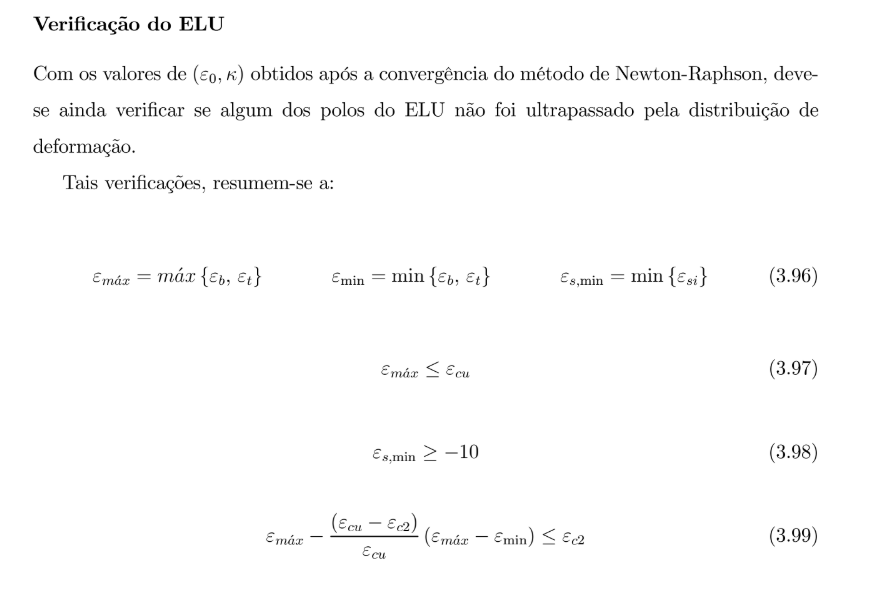

%curv positiva
if epsilontopo >= epsilonbase
    if (epsilontopo <= epsiloncu && epsilon0 + (ytopo - h*(epsiloncu-epsilonc2)/epsiloncu)*k <= epsilonc2 && (epsilon0 + k*ys(1)) >= -10)
        elu = true;
    else
        elu = false;
    end

%curv negativa
else
    if (epsilonbase <= epsiloncu && (epsilon0 + (ybase + h*(epsiloncu-epsilonc2)/epsiloncu)*k) <= epsilonc2 && (epsilon0 + k*ys(nc)) >= -10)
        elu = true;
    else
        elu = false;
    end
end

if elu == false
    fprintf ('Solução não está dentro da região viável do ELU.\n\nA configuração de deformação é (epsilon0,k) = (%.6f, %.6f) \n', epsilon0, k);
    
else
    fprintf ('Solução encontrada! Resiste e está dentro da região viável.\n\nA configuração de deformação é (epsilon0,k) = (%.6f, %.6f) \n', epsilon0, k);
    
end 

Solução encontrada! Resiste e está dentro da região viável.

A configuração de deformação é (epsilon0,k) = (2.060224, 0.965825) 
